clearvars;clc;

data_folder = '.\data\';
patient = 'ai6_micontinuous\';
files{1} = 'ai6.20180316.153104.offline.mi.mi_bhbf.gdf';
files{2} = 'ai6.20180316.154006.offline.mi.mi_bhbf.gdf';
files{3} = 'ai6.20180316.154811.offline.mi.mi_bhbf.gdf';
files{4} = 'ai6.20180316.160351.online.mi.mi_bhbf.ema.gdf';
files{5} = 'ai6.20180316.161026.online.mi.mi_bhbf.dynamic.gdf';
files{6} = 'ai6.20180417.164812.online.mi.mi_bhbf.ema.gdf';
files{7} = 'ai6.20180417.165259.online.mi.mi_bhbf.dynamic.gdf';
files{8} = 'ai6.20180529.151753.online.mi.mi_bhbf.ema.gdf';
files{9} = 'ai6.20180529.152240.online.mi.mi_bhbf.dynamic.gdf';
% patient = 'lezione\';
% files{1} = 'ah7.20170613.161402.offline.mi.mi_bhbf.gdf';
% files{2} = 'ah7.20170613.162331.offline.mi.mi_bhbf.gdf';
% files{3} = 'ah7.20170613.162934.offline.mi.mi_bhbf.gdf';
% files{4} = 'ah7.20170613.170929.online.mi.mi_bhbf.ema.gdf';
% files{5} = 'ah7.20170613.171649.online.mi.mi_bhbf.dynamic.gdf';
% files{6} = 'ah7.20170613.172356.online.mi.mi_bhbf.dynamic.gdf';
% files{7} = 'ah7.20170613.173100.online.mi.mi_bhbf.ema.gdf';
%mnemonic codes
code.fixation = 786;
code.cue_BH = 773;
code.cue_BF = 771;
code.cue_rest = 783;
code.feedback = 781;
modality.offline = 0;
modality.online = 1;
data_path = './data/';
%sub-band of frequencies of psd we are interested in
selected_frequences = (4:2:48)';
channel_labels  = {'Fz', 'FC3', 'FC1', 'FCz', 'FC2', 'FC4', 'C3', 'C1', 'Cz', 'C2', 'C4', 'CP3', 'CP1', 'CPz', 'CP2', 'CP4'};
num_features = 3;
%load the weigths to select the features
feature_weights = load('features_filter.mat').features_filter';


## load EEG

EEG_data = cell(size(files));

for file = 1 : length(files)
    [s,h] = sload(fullfile(data_path, patient, files{file}));
    EEG_data{file}.signal = s;
    EEG_data{file}.header = h;
end


## convert EEG into PSD

PSD_data = cell(size(EEG_data));
original_frequences=nan;
for eeg_i = 1 : length(EEG_data)
    signal = EEG_data{eeg_i}.signal;
    header = EEG_data{eeg_i}.header;
    PSD_data{eeg_i} = psd_extraction(signal, header);
    %adding modality info
    if contains(files{eeg_i},"offline")
        PSD_data{eeg_i}.modality = modality.offline;
    elseif contains(files{eeg_i},"online")
        PSD_data{eeg_i}.modality = modality.online;
    else
        error(['Unknown modality for file: ' eeg_i]);
    end
    original_frequences = PSD_data{eeg_i}.frequences;
end

[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events


## concatenate files and label data

[PSD, EVENT, run_labels, modality_labels] = concatenatePSD(PSD_data);

num_windows  = size(PSD, 1);
[cue_type_labels, trial_labels] = labelData(EVENT, num_windows);

offline_data_index = (modality_labels == modality.offline);
online_data_index = (modality_labels == modality.online);
bf_bh_data_index = (cue_type_labels == code.cue_BH | cue_type_labels == code.cue_BF);


## log and sub-frequences extraction

PSD = log(PSD);
[PSD, frequences] = extractFrequences(PSD, original_frequences, selected_frequences);
    

## convert PSDs into dataset for the classifiers


classes = unique(cue_type_labels(bf_bh_data_index));
[X, selected_freq_chan_index , fisher_score_run] = psd2features(PSD, run_labels, cue_type_labels, classes, num_features ,feature_weights);

## compute mean fisher's score

mean_fisher_score = mean(fisher_score_run,3);

## filter mean fisher's score

filtered_mean_Fisher = mean_fisher_score .* feature_weights;

## generate map of selected features

features_mask = zeros(size(mean_fisher_score));

for k = 1 : length(selected_freq_chan_index)
    feature_index = selected_freq_chan_index{k};
    features_mask(feature_index(1), feature_index(2)) = 1;
end

## Visualization Fisher score

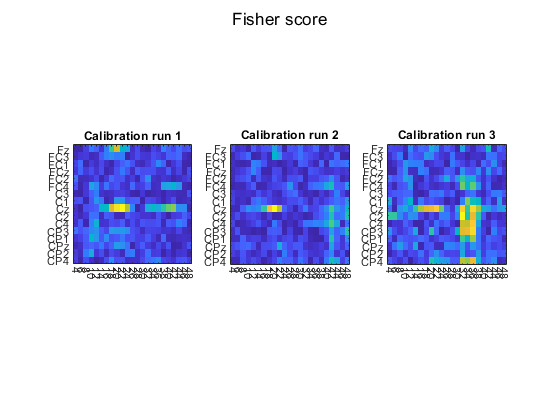

channelId  = 1:length(channel_labels);

NumRuns = length(EEG_data);
NumFreqs = length(frequences);
NumChans = length(channel_labels);
classId    = [773 771];
classLb    = {'both hands', 'both feet'};
nclasses   = length(classId);
modalityId = [0 1];
modalityLb = {'offline', 'online'};
OfflineRuns = [1 2 3];
climits = [];
handles = nan(NumRuns, 1);
fig1 = figure;

for rId = 1:length(OfflineRuns)
    subplot(1, 3, rId);
    imagesc(fisher_score_run(:, :, OfflineRuns(rId))');
    axis square;
    set(gca, 'XTick', 1:NumFreqs);
    set(gca, 'XTickLabel', frequences);
    set(gca, 'YTick', 1:NumChans);
    set(gca, 'YTickLabel', channel_labels);
    xtickangle(-90);
    
    title(['Calibration run ' num2str(OfflineRuns(rId))]);
    
    climits = cat(2, climits, get(gca, 'CLim'));
    handles(OfflineRuns(rId)) = gca;
end


sgtitle('Fisher score');

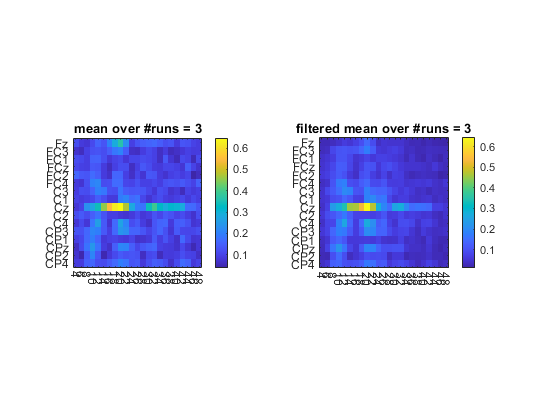

fig2=figure;
subplot(1,2,1);
imagesc(mean_fisher_score');
axis square;
set(gca, 'XTick', 1:NumFreqs);
set(gca, 'XTickLabel', frequences);
set(gca, 'YTick', 1:NumChans);
set(gca, 'YTickLabel', channel_labels);
xtickangle(-90);
colorbar;

title(['mean over #runs = ' num2str(OfflineRuns(rId))]);

subplot(1,2,2);
imagesc(filtered_mean_Fisher');
axis square;
set(gca, 'XTick', 1:NumFreqs);
set(gca, 'XTickLabel', frequences);
set(gca, 'YTick', 1:NumChans);
set(gca, 'YTickLabel', channel_labels);
xtickangle(-90);
colorbar;

title(['filtered mean over #runs = ' num2str(OfflineRuns(rId))]);

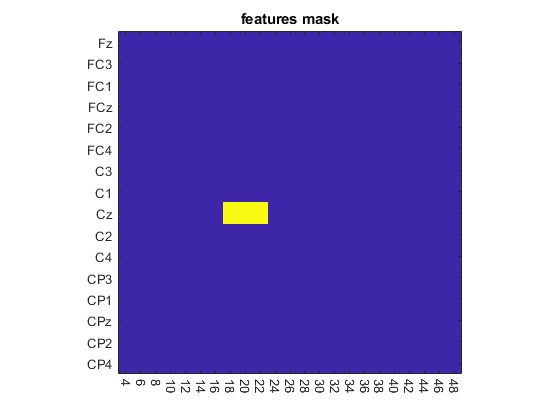



figure3=figure;
imagesc(features_mask');
axis square;
set(gca, 'XTick', 1:NumFreqs);
set(gca, 'XTickLabel', frequences);
set(gca, 'YTick', 1:NumChans);
set(gca, 'YTickLabel', channel_labels);
xtickangle(-90);

title('features mask');

## train the classifier on offline data

train_index = (offline_data_index & bf_bh_data_index);
test_index = (online_data_index & bf_bh_data_index);
bh_index = (cue_type_labels== code.cue_BH);
bf_index = (cue_type_labels== code.cue_BF);

train_set = X(train_index,:);
label_train = cue_type_labels(train_index);
test_set = X(test_index,:);
label_test = cue_type_labels(test_index);

## multi classifier

%model = train_binary_model(train_set, label_train);
model = fitcdiscr(train_set,label_train,"DiscrimType","quadratic");

## train set results

predicted_labels = predict(model, train_set);
accuracy_tot = 100*sum(label_train == predicted_labels)/length(label_train);
accuracy_bh = 100*sum(predict(model,X(train_index & bh_index,:))==code.cue_BH)/sum(train_index & bh_index);
accuracy_bf = 100*sum(predict(model,X(train_index & bf_index,:))==code.cue_BF)/sum(train_index & bf_index);

disp(["the accuracy on train set is " accuracy_tot]);

    "the accuracy on train set is "    "72.0056"



disp(["the accuracy on train set of BH is " accuracy_bh]);

    "the accuracy on train set of BH is "    "78.8173"



disp(["the accuracy on train set of BF is " accuracy_bf]);

    "the accuracy on train set of BF is "    "65.1957"



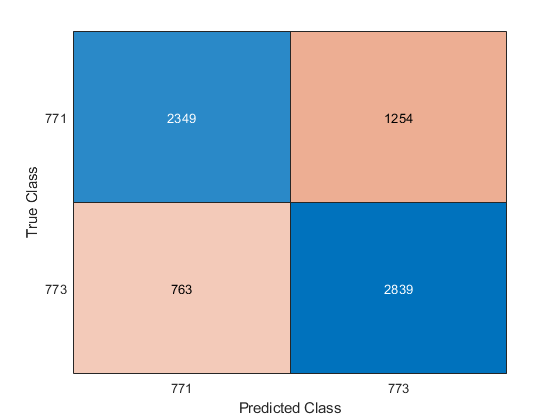

confusionchart(label_train, predicted_labels);

## test the model on online data

predicted_labels_test = predict(model, test_set);
accuracy_test = 100*sum(label_test == predicted_labels_test)/length(label_test);
accuracy_bh_test = 100*sum(predict(model,X(test_index & bh_index,:))==code.cue_BH)/sum(test_index & bh_index);
accuracy_bf_test = 100*sum(predict(model,X(test_index & bf_index,:))==code.cue_BF)/sum(test_index & bf_index);

disp(["the accuracy on test set is " accuracy_test  ]);

    "the accuracy on test set is "    "70.7441"



disp(["the accuracy on test set of BH is " accuracy_bh_test]);

    "the accuracy on test set of BH is "    "70.1849"



disp(["the accuracy on test set of BF is " accuracy_bf_test]);

    "the accuracy on test set of BF is "    "71.4075"



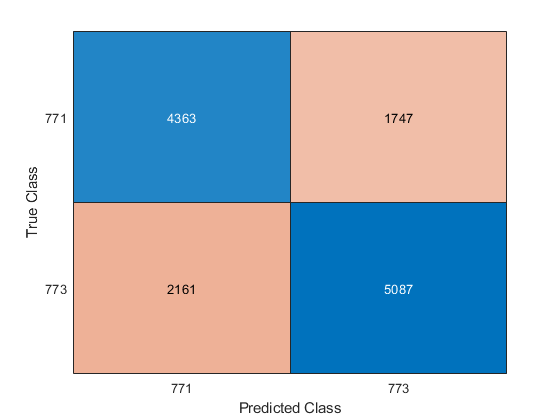


confusionchart(label_test, predicted_labels_test);

## Evidence accumulation

classify and accumulate evidence over the continuous-feedback period of online runs

the evidence accumulation is based on the posterior probability of class 771 both feet

% index for online data from cue to feedback
accumulation_index = (cue_type_labels~=0 & modality_labels==modality.online);
% online data from cue to feedback
accumulation_data= X(accumulation_index, :);
% trial labels for online data from cue to feedback
accumulation_trial_labels = trial_labels(accumulation_index);

%predict on data
[~,post_probability] = predict(model, accumulation_data);

%coefficient that determines how the system respond to the new sample (high-> conservative, low->responsive)
alpha = 0.45;
beta = 0.6;
conservative_amp = 0.8;
num_samples = length(accumulation_data);
num_classes = length(classes);
%reset accumulation to the base probability of this class = 1/num_classes
reset_accumulation = 1./num_classes;
%contains the accumulation evidence for the sample_i of the training set
%accumulator = exponential_smoothing(post_probability, num_classes, accumulation_trial_labels, alpha);
accumulator = dynamic_smoothing(post_probability, num_classes, accumulation_trial_labels, alpha, beta, conservative_amp);

## performances

the performances are evaluated over the feedback period

up_threshold = 0.7;
down_threshold = 0.3;
% index for the feedback part of the data used in accumulation
feedback_index = getLabelsForEventType(EVENT, code.feedback, num_windows);
% name for trials
trials = unique(accumulation_trial_labels);
num_trials = length(trials);
% vector for saving the class predicted by the evidence accumulator
predicted_class_accumulation = nan(size(trials));
% vector for saving the true class for the trial
true_class_accumulation = nan(size(trials));


for trial_i = 1:num_trials
    % index for extracting only the data in this trial
    this_trial = trials(trial_i);
    % index for extracting only the feedback data in this trial
    this_trial_feedback_index = feedback_index & (trial_labels==this_trial);
    % evidences accumulated for this trial
    % (accumulation_index) maps this_trial_feedback_index to the size of accumulation data
    trial_accumulation = accumulator(this_trial_feedback_index(accumulation_index));
    
    %insert the true class
    true_class_accumulation(trial_i) = unique(cue_type_labels(this_trial_feedback_index));
    
    %find the critical samle that exceeds any threshold
    critial_sample = find( (trial_accumulation >= up_threshold) | (trial_accumulation <= down_threshold), 1, 'first' );
    
    %analysis on the critical sample to determine the predicted class to assign
    if(isempty(critial_sample))
        % no threshold exceded so this trial is predicted as rest
        predicted_class_accumulation(trial_i) = code.cue_rest;
        continue;
    end
    
    if(trial_accumulation(critial_sample) >= up_threshold)
        % beaing based on both feet posterior probability if the upper
        % threshold is exceeded this trial is calssified as both feet
        predicted_class_accumulation(trial_i) = code.cue_BF;
    elseif (trial_accumulation(critial_sample) <= up_threshold)
        predicted_class_accumulation(trial_i) = code.cue_BH;
    end
end

% index for the trials that are not of resting in the true label
active_trials_index = true_class_accumulation ~= code.cue_rest;
% index for the trials that are of resting  in the true label
rest_trials_index = true_class_accumulation == code.cue_rest;

PerfActive  = 100 * (sum(true_class_accumulation(active_trials_index) == predicted_class_accumulation(active_trials_index))./sum(active_trials_index));
PerfResting = 100 * (sum(true_class_accumulation(rest_trials_index) == predicted_class_accumulation(rest_trials_index))./sum(rest_trials_index));

RejTrials = predicted_class_accumulation == code.cue_rest;

PerfActive_rej = 100 * (sum(true_class_accumulation(active_trials_index & ~RejTrials) == predicted_class_accumulation(active_trials_index & ~RejTrials))./sum(active_trials_index & ~RejTrials));
disp(["action_typeA -> action_typeA = " PerfActive]);

    "action_typeA -> action_typeA = "    "46.6667"



disp(["rest -> rest = " PerfResting]);

    "rest -> rest = "    <missing>



disp(["not rest -> not rest = " PerfActive_rej]);

    "not rest -> not rest = "    "86.1538"



## plot results of evidence accumulation

% fig1 = figure;
% 
% CueClasses    = [771 783 773];
% LbClasses     = {'both feet', 'rest', 'both hands'};
% ValueClasses  = [1 0.5 0];
% Threshold     = 0.7;
% 
% SelTrial = 50;

% Trial 15: good rest
% Trial 80: bad rest
% Trial 55: good both hands
% % Trial 58: good both feet
% 
% cindex = Tk == SelTrial;
% [~, ClassIdx] = ismember(unique(Ck(cindex)), CueClasses);
% 
% GreyColor = [150 150 150]/255;
% LineColors = {'b', 'g', 'r'};
% 
% hold on;
% % Plotting raw probabilities
% plot(pp(cindex, 1), 'o', 'Color', GreyColor);
% 
% % Plotting accumulutated evidence
% plot(ipp(cindex), 'k', 'LineWidth', 2);
% 
% % Plotting actual target class
% yline(ValueClasses(ClassIdx), LineColors{ClassIdx}, 'LineWidth', 5);
% 
% % Plotting 0.5 line
% yline(0.5, '--k');
% 
% % Plotting thresholds
% yline(Threshold, 'k', 'Th_{1}');
% yline(1-Threshold, 'k', 'Th_{2}');
% hold off;
% 
% grid on;
% ylim([0 1]);
% xlim([1 sum(cindex)]);
% legend('raw prob', 'integrated prob');
% ylabel('probability/control')
% xlabel('sample');
% title(['Trial ' num2str(SelTrial) '/' num2str(NumTrials) ' - Class ' LbClasses{ClassIdx} ' (' num2str(CueClasses(ClassIdx)) ')']);

